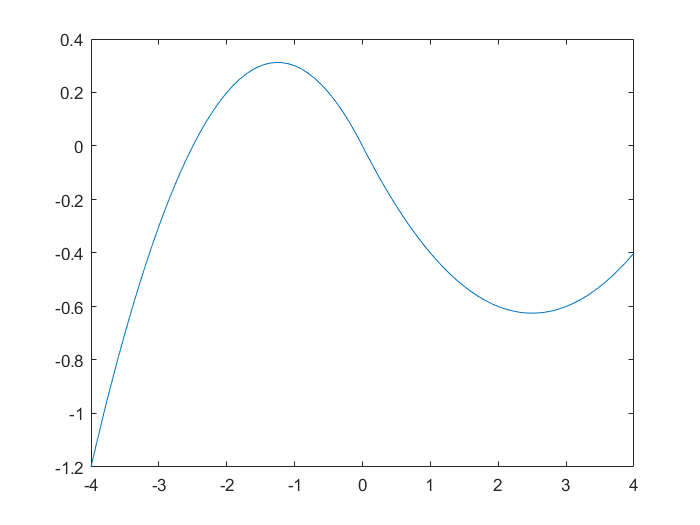

clear all;
close all;
% illustrate magnetic field 
x = -4 : 0.1 : 4;
field1 = arrayfun(@(x) magnetic_model(x), x);
figure;
plot(x, field1)

## System configuration

% simulate IMU noise
sigma_acceleration = 0.1;
% simulate magnetometer noise
sigma_magnetometer = 0.005;
% displacement of sensors
sensor_disp = 0.1;
% initial position
init_pos = [-10, 0, 0];
% velocity 
init_vel = [4, 0, 0];
% sampling interval
fs = 100;
dT = 1 / fs;

## trajectory

traj = kinematicTrajectory('Position', init_pos, ...
                           'Velocity', init_vel,...
                           'Orientation', quaternion([0 0 0], 'eulerd', 'ZYX', 'frame'));

duration = 40;
numSamples = duration*fs;

% just positive acceleration 
%accBody = [repmat([-0.2, 0, 0], numSamples/2, 1); repmat([-0.3, 0, 0], numSamples/4, 1); repmat([0, 0, 0], numSamples/4, 1)];
accBody = [repmat([-0.2, 0, 0], numSamples/2, 1); repmat([-0.3, 0, 0], numSamples/2, 1)];
angVelBody = zeros(numSamples,3);


q = ones(numSamples,1,'quaternion');
[pos, orientationNED, vel, accNED, angVelNED] = traj(accBody, angVelBody);

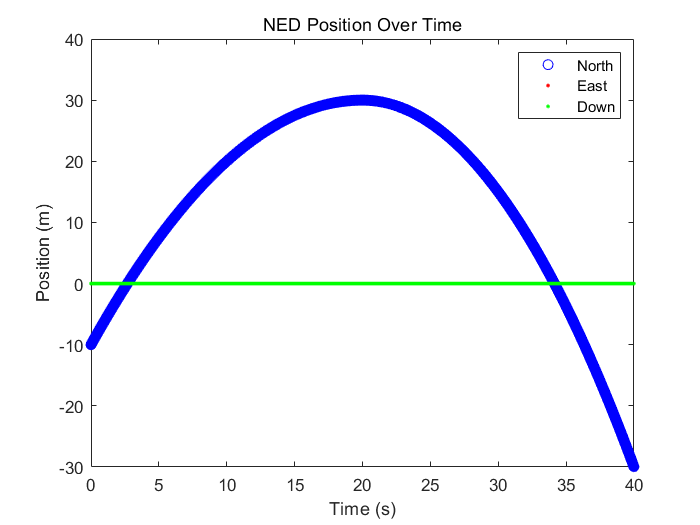

timeVector = 0:1/fs:(duration-1/fs);
figure(3)
plot(timeVector,pos(:,1),'bo',...
     timeVector,pos(:,2),'r.',...
     timeVector,pos(:,3),'g.')
xlabel('Time (s)')
ylabel('Position (m)')
title('NED Position Over Time')
legend('North','East','Down')

## Generate IMU data

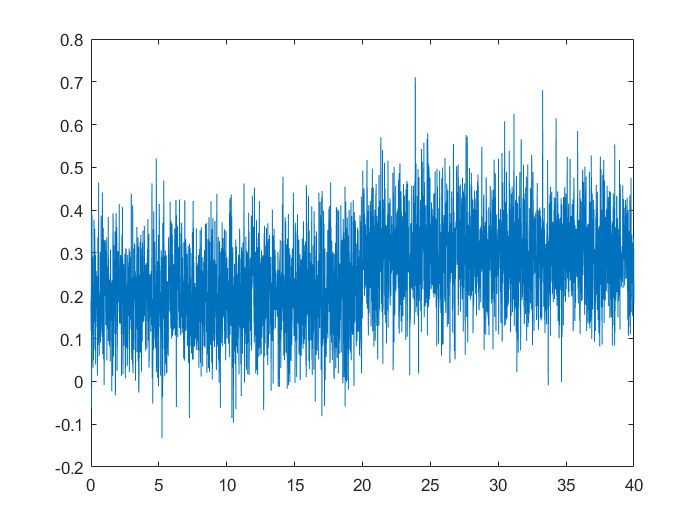

%accparams = accelparams('ConstantBias',0.09);
%IMU = imuSensor('SampleRate', fs, 'Accelerometer', accparams);
IMU = imuSensor('SampleRate', fs);

[accelerometerReadings,gyroscopeReadings] = IMU(accBody, angVelBody);

accelerometerReadings = accelerometerReadings + sigma_acceleration * randn(size(accelerometerReadings));
%subplot(1, 2, 1);
plot(timeVector, accelerometerReadings(:, 1));

% subplot(1, 2, 1);
% plot(timeVector, accelerometerReadings);

## Generate Magnetometer data

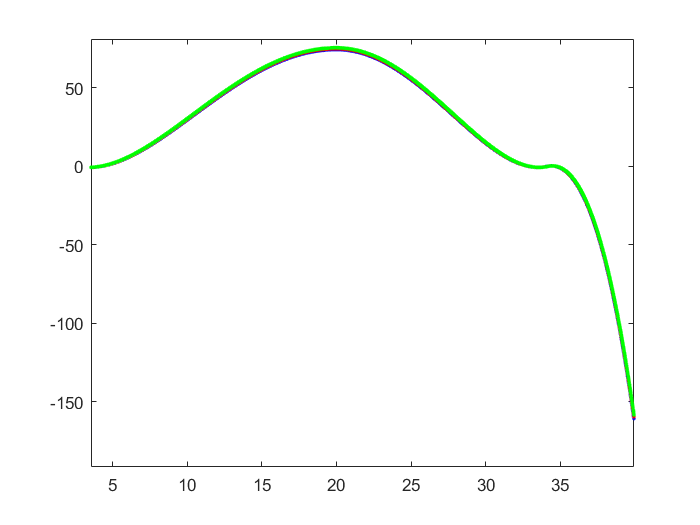

model = @magnetic_model;
magnetometerReadings = zeros(numSamples, 3);
for i = 1 : size(pos, 1)
    [~, magnetometerReadings(i, 1)] = magnetometer(model, pos(i, 1) - sensor_disp, sigma_magnetometer);
    [~, magnetometerReadings(i, 2)] = magnetometer(model, pos(i, 1), sigma_magnetometer);
    [~, magnetometerReadings(i, 3)] = magnetometer(model, pos(i, 1) + sensor_disp, sigma_magnetometer);
end
figure;
plot(timeVector,magnetometerReadings(:,1),'b.',...
     timeVector,magnetometerReadings(:,2),'r.',...
     timeVector,magnetometerReadings(:,3),'g.')

## EKF Setup

p = polyfit([init_pos(1)-sensor_disp, init_pos(1), init_pos(1)+sensor_disp], magnetometerReadings(1, :), 2);
initialStateGuess = [init_pos(1); init_vel(1); p.'];
obj = extendedKalmanFilter(@StateTransitionFcn, @MeasurementFcn, initialStateGuess);
obj.StateCovariance = diag([1, 1, 4, 4, 4]);
G = [1/2*dT^2; dT];

Q_magnetic = diag([0.1; 1; 1]);
%obj.ProcessNoise =  G * G.' * sigma_acceleration;
Q_posVel = G * G.' * sigma_acceleration;

obj.ProcessNoise = blkdiag(Q_posVel, Q_magnetic);
obj.MeasurementNoise = sigma_magnetometer^2 * eye(3);

X = zeros(numSamples, 5);
P = zeros(numSamples, 5 , 5);
for i = 1 : numSamples
    correct(obj, magnetometerReadings(i, :).', sensor_disp);
    X(i, :) = obj.State.';
    P(i, :, :) = obj.StateCovariance;
    predict(obj, -accelerometerReadings(i, 1), dT);

end

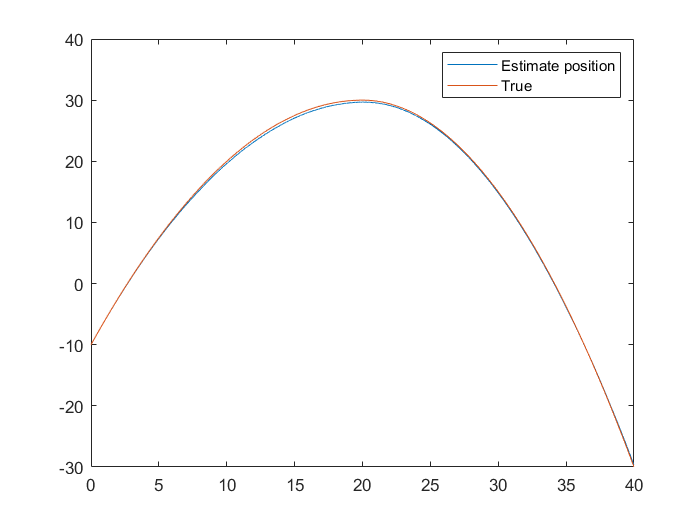

figure;
plot(timeVector, X(:, 1));
hold on;
plot(timeVector,pos(:,1));
legend('Estimate position', 'True');

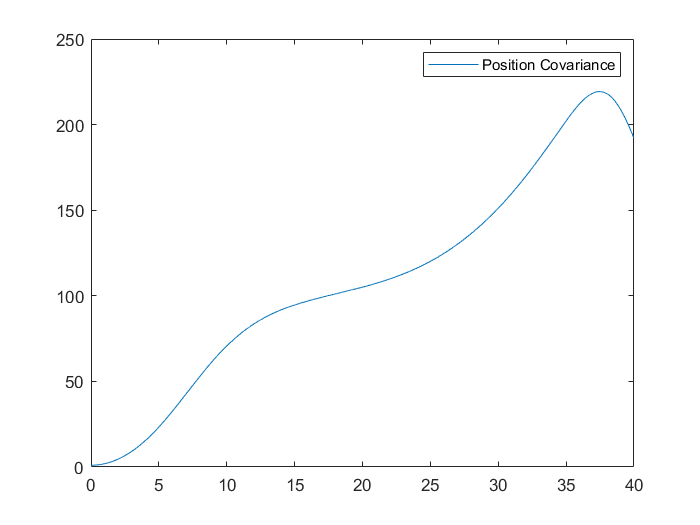

figure;
plot(timeVector, P(:, 1, 1));
legend('Position Covariance')

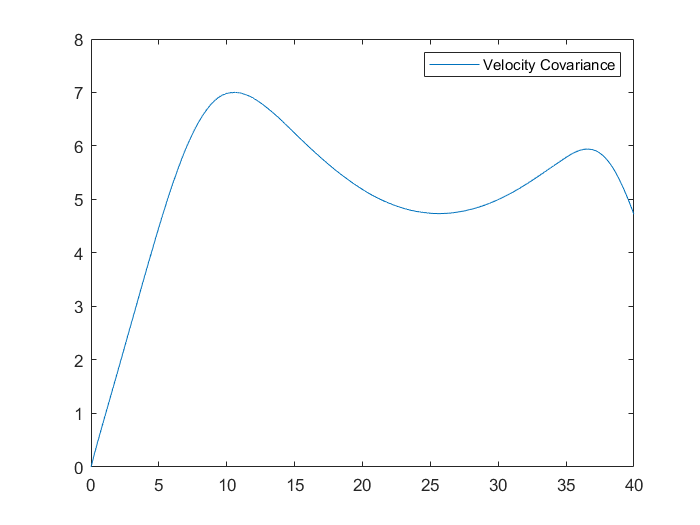

plot(timeVector, P(:, 2, 1));
legend('Velocity Covariance')

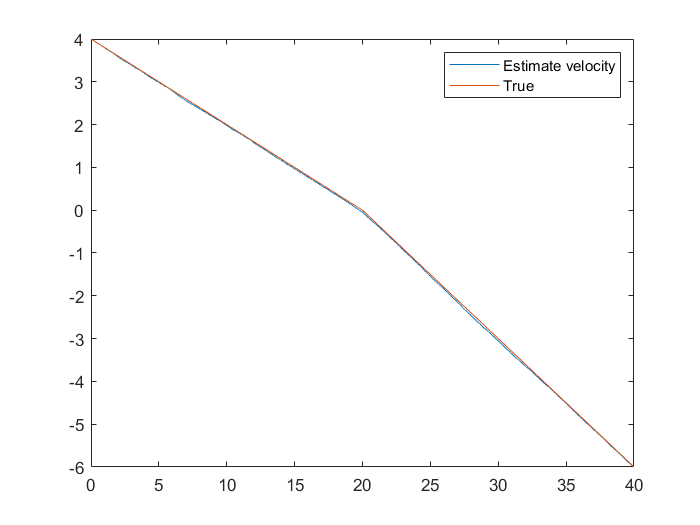

figure
plot(timeVector, X(:, 2));
hold on;
plot(timeVector, vel(:, 1));
legend('Estimate velocity', 'True');